Estimadores estadísticos:

Estimador de Máxima Verosimilitud (MLE):

Este estimador lo que pretende es que se obtenga el valor de $\hat{A}$ que maximise $P(x|\hat{A})$, donde $\hat{A}$ hace referencia a la variable que se desea estimar y $x$ es eñ vector de las observaciones. 

Se procede obteniendo los datos (observaciones)

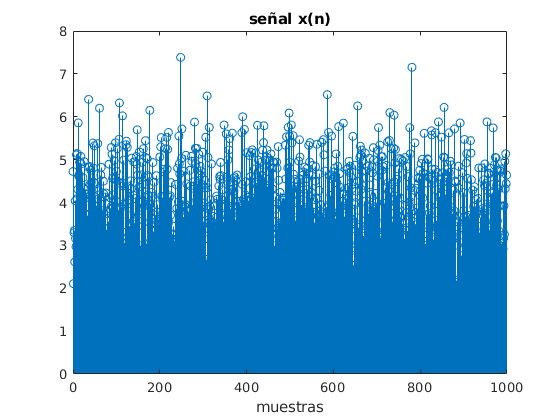

A=4; % valor DC de la señal x(n) "desconocido"
N=1000; % número de muestras de x(n)
xn=A+normrnd(0,1,N,1); % señal con ruido Gaussiano (media=0, sigma=1)
stem([0:N-1],xn)
xlabel('muestras')
title('señal x(n)')

En este ejemplo se utilizará una estrategia de optimización (gradiente descendente), pero existe una solución analítica.

A continuación verá el uso del método mencionado:

%punto de partida, un valor cualquiera
A_h=xn(1);
%parámetros del algoritmo 
stop = 1;
step=0.1;
max_iter=500;
iter=0;
%loop de optimización
while stop > 0.0000001 & iter<max_iter
    A_hp=A_h;
    grad=dLogP_xth(xn,A_h);
    A_h=A_h-step*grad;
    stop = abs(A_h-A_hp);
    iter = iter+1;
end
cd=sprintf('Valor estimado: %8.6f',A_h);
disp(cd)

Valor estimado: 3.971357


error = abs(A-A_h)

error = 0.0286